# ROS2 - Stereo Camera

clc; clear; close all;

## Node & Publisher

% Create node
ros2node = ros2node("stereo_camera_node");

% Create image publishers
leftPub = ros2publisher(ros2node, "/stereo/left/image_raw", "sensor_msgs/Image");
rightPub = ros2publisher(ros2node, "/stereo/right/image_raw", "sensor_msgs/Image");

## Cameras Init

webcamlist % List of available cameras

ans = 3×1 cell array
    {'HD Pro Webcam C920'                                }
    {'HD Webcam'                                         }
    {'Camera (NVIDIA Broadcast) (Windows Virtual Camera)'}


% Initialize cameras
leftCam = webcam(1);
rightCam = webcam(2);

ratePublisher = ros2rate(ros2node,5) % Desired rate = 5 Hz

ratePublisher =   ros2rate with properties:

    IsSimulationTime: 0
         DesiredRate: 5
       DesiredPeriod: 0.2000
       OverrunAction: 'slip'
    TotalElapsedTime: 0.0033
          LastPeriod: NaN


reset(ratePublisher)

## Loop for displaying the cameras

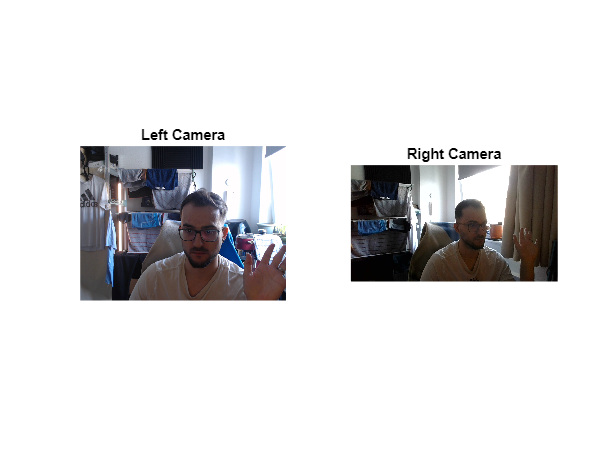

for i = 1:1000
    leftFrame = snapshot(leftCam);
    rightFrame = snapshot(rightCam);

    leftMsg = ros2message(leftPub);
    rightMsg = ros2message(rightPub);

    % Display images side by side
    subplot(1,2,1); imshow(leftFrame); title('Left Camera');
    subplot(1,2,2); imshow(rightFrame); title('Right Camera');
    drawnow;

    send(leftPub, leftMsg);
    send(rightPub, rightMsg);

    waitfor(ratePublisher);
end